# Documentation

The first part of the documentation use data from Želi et al. [1] which are openly available on Zenodo at [https://zenodo.org/record/3937500.](https://zenodo.org/record/3937500.) These data are four different simulations of the first and second-order profiles of the flow characteristics in the stable 1D-atmospheric boundary layer. 

The second part of the documentation sue data from Allaerts et al. [2], which are openly available on [https://data.4tu.nl/datasets/30bdab8c-dee8-40cf-9761-578c9f8392ae](https://data.4tu.nl/datasets/30bdab8c-dee8-40cf-9761-578c9f8392ae) These data comes from two days of LES simulations in the atmospheric boundary layer. I cannot put the dataset inside the submission because it is quite big (5 GB). So the user will have to download the data beforehand. 

The script explore the data for two purposes:

- Check that a simple Matlab implementation of the Bulk Richardson Number gives realistic results

- Apply a simple shallow Neural network to predict the profile of the standard deviation of the along-wind velocity component, knowing only the profiles of the two hroizontal mean velocity component and the profile of the standard deviation of the vertical velocity component.

**References**

[1] Želi, V., Brethouwer, G., Wallin, S.,  & Johansson, A. V. (2020). Modelling of stably stratified  atmospheric boundary layers with varying stratifications. *Boundary-Layer Meteorology*, *176*(2), 229-249.

[2] Allaerts, D., Quon, E., & Churchfield, M. (2023). Using observational mean‐flow data to drive large‐eddy simulations of a  diurnal cycle at the SWiFT site. Wind Energy.

## PART 1: data from Želi et al.

### Loading the data from Želi et al.

clearvars;close all;clc;
load('data.mat','z','H','U','V','Ri','theta','stdU','stdV','stdW','u_star');
leg = {'case 1','case 2','case 3','case 4'};

leg = 1×4 cell array
    {'case 1'}    {'case 2'}    {'case 3'}    {'case 4'}


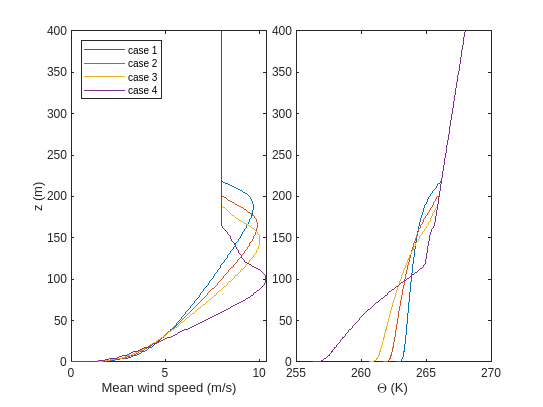


Ri(Ri>0.5)=nan; % Richardson number above 0.5 are set as NaN
u_star(u_star<0.001) = nan; % Low friction velocity as set as NaN

[Nsamples,N]=size(z);


clf;close all;
figure
tiledlayout(1,2,"TileSpacing","tight")
nexttile
plot(H,z(1,:),'linewidth',1.2)
ylabel('z (m)')
xlabel('Mean wind speed (m/s)')
legend(leg,'Location','northwest')
nexttile
plot(theta,z(1,:),'linewidth',1.2)
xlabel('\Theta (K)')

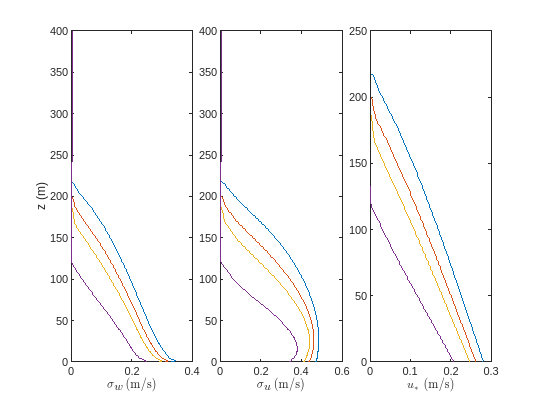


clf;close all;
figure
tiledlayout(1,3,"TileSpacing","tight")
nexttile
plot(stdW,z(1,:),'linewidth',1.2)
ylabel('z (m)')
xlabel('$\sigma_w$ (m/s)','interpreter','latex')
nexttile
plot(stdU,z(1,:),'linewidth',1.2)
xlabel('$\sigma_u$ (m/s)','interpreter','latex')
nexttile
plot(u_star,z(1,:),'linewidth',1.2)
xlabel('$u_*$ (m/s)','interpreter','latex')

### Estimate the Bulk Richardson number

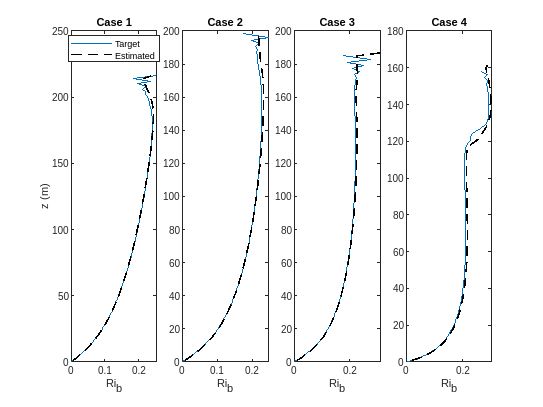

Ri1 = zeros(Nsamples,N-1);
z1 = zeros(Nsamples,N-1);
for jj=1:Nsamples,
    for ii=1:N-1
        [Ri1(jj,ii)] = BulkRichardson(theta(jj,ii:ii+1),U(jj,ii:ii+1),V(jj,ii:ii+1),z(jj,ii:ii+1));
        z1(jj,ii)= mean(z(jj,ii:ii+1));
    end
end
Ri1(Ri1>0.5)=nan;
Ri1 = interp1(z1(1,:),Ri1',z(1,:))';

clf;close all;
figure
tiledlayout(1,Nsamples,"TileSpacing","tight")
for ii=1:Nsamples,
    nexttile
    
    plot(Ri(ii,:),z(1,:),'linewidth',1.2)
    title(['Case ' , num2str(ii)])
    hold on
    plot(Ri1(ii,:),z(1,:),'k--','linewidth',1.2)
    if ii==1,
        legend('Target','Estimated','location','best');
        ylabel('z (m)')
    end
    xlabel('Ri_b')
end

### Shallow ANN with full vertical profiles  of $\sigma_u$

We assume that all heights are known for the along-wind velocity component. The goal is to retrieve the full profile of $\sigma_u$

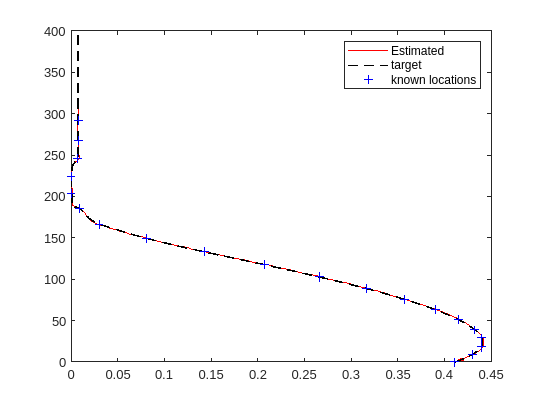

indSamples = [1 2 4] ;
indMinZ = 1;
indMaxZ = 200;
indZ = [indMinZ:10:indMaxZ];
% Train the ANN
[net] = get_stdU(z(indSamples,[indMinZ:indMaxZ]),...
    stdW(indSamples,[indMinZ:indMaxZ]),...
    U(indSamples,[indMinZ:indMaxZ]),...
    V(indSamples,[indMinZ:indMaxZ]),...
    stdU(indSamples,[indMinZ:indMaxZ]));


% Check that the prediction is OK with sample no 3
indTarget =  [3];
clear x
x(1,:) = z(indTarget,[indMinZ:indMaxZ]);
x(2,:) = stdW(indTarget,[indMinZ:indMaxZ]);
x(3,:) = U(indTarget,[indMinZ:indMaxZ]);
x(4,:) = V(indTarget,[indMinZ:indMaxZ]);

% use the trained ANN
y = net(x);

clf;close all;
figure
plot(y,z(1,[indMinZ:indMaxZ]),'r','linewidth',1.2)
hold on
plot(stdU(indTarget,:),z(1,:),'k--','linewidth',1.2)
plot(stdU(indTarget,indZ),z(1,indZ),'b+')
legend('Estimated','target','known locations')

### Shallow ANN with partial vertical profiles  of $\sigma_u$

We assume only a few number of heights are known for the along-wind velocity component. The goal is to retrieve the full profile of $\sigma_u$

indSamples = [1 2 4];
indMinZ = 10;
indMaxZ = 200;

indMaxZ = 200

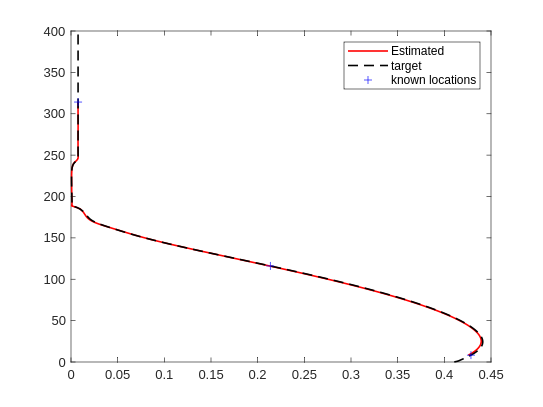

indZ = [indMinZ, 100, indMaxZ];
% Train the ANN
dummyU = nan(size(stdU));
dummyU(:,indZ) = stdU(:,indZ); 

clear net
[net] = get_stdU(z(indSamples,[indMinZ:indMaxZ]),...
    stdW(indSamples,[indMinZ:indMaxZ]),...
    U(indSamples,[indMinZ:indMaxZ]),...
    V(indSamples,[indMinZ:indMaxZ]),...
    stdU(indSamples,[indMinZ:indMaxZ]));


% Check that the prediction is OK with sample no 3
indTarget =  [3];
clear x
x(1,:) = z(indTarget,[indMinZ:indMaxZ]);
x(2,:) = stdW(indTarget,[indMinZ:indMaxZ]);
x(3,:) = U(indTarget,[indMinZ:indMaxZ]);
x(4,:) = V(indTarget,[indMinZ:indMaxZ]);

% use the trained ANN
y = net(x);

clf;close all;
figure
plot(y,z(1,[indMinZ:indMaxZ]),'r','linewidth',1.2)
hold on
plot(stdU(indTarget,:),z(1,:),'k--','linewidth',1.2)
plot(stdU(indTarget,indZ),z(1,indZ),'b+')
legend('Estimated','target','known locations')

## PART 2: data from Allaerts et al.

The dataset "planarAverages.nc" should be downloaded from [https://data.4tu.nl/datasets/30bdab8c-dee8-40cf-9761-578c9f8392ae](https://data.4tu.nl/datasets/30bdab8c-dee8-40cf-9761-578c9f8392ae)

### Loading the data from Allaerts et al.

% Check if the data are already donwloaded. 
filename = 'planarAverages.nc';
if ~exist(filename,'file'),
    error('You should download the data file ''planarAverages.nc'' from https://data.4tu.nl/datasets/30bdab8c-dee8-40cf-9761-578c9f8392ae ')
end

% ncdisp(filename);

% Get height and time
z = ncread(filename,'height')';
t = datetime(2013,11,08,12,0,0) + seconds(ncread(filename,'datetime')/1000);
dt = seconds(median(diff(t)));
fs = 1./dt;

% Get velocity data + temperature data
u = sqrt(ncread(filename,'u'));
v = sqrt(ncread(filename,'v'));
theta = 273.15 + sqrt(ncread(filename,'theta'));

% Get some of the 2nd order turbulence characteristics
stdU = sqrt(ncread(filename,'uu'));
stdV = sqrt(ncread(filename,'vv'));
stdW = sqrt(ncread(filename,'ww'));
wT = sqrt(ncread(filename,'wtheta'));
u_star = (ncread(filename,'uw').^2 + ncread(filename,'vw').^2).^(0.25) ;


### Data visualisation

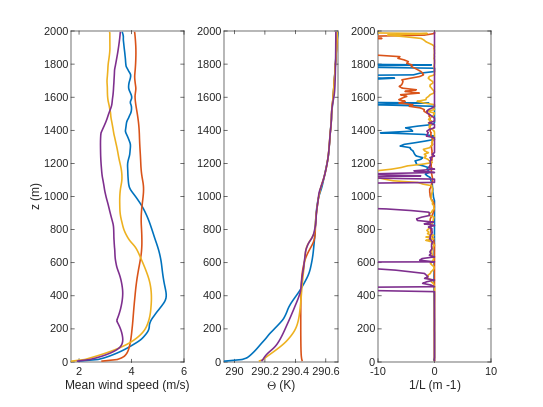

set(0, 'DefaultFigureRenderer', 'painters');
% Four subsamples are selected and averaged over 10 min
Nsamples = 4;
Nz = numel(z);
tStart = NaT(1,Nsamples);
tEnd = NaT(1,Nsamples);
for ii=1:Nsamples
    tStart(ii) = datetime(2013,11,08,13,0,0) + hours(8*(ii-1));
    tEnd(ii) = tStart(ii)+minutes(10);
end

% Extract four subsamples for visualization purpose
[U,V,H,stdU1,stdV1,stdW1,u_star1,wT1,theta1,L] = getSubSamples(t,tStart,tEnd,...
    u,v,stdU,stdV,stdW,u_star,wT,theta);

clf;close all;
figure
tiledlayout(1,3,"TileSpacing","tight")
nexttile
plot(H,z,'linewidth',1.2)
ylabel('z (m)')
xlabel('Mean wind speed (m/s)')
% legend(leg,'Location','northwest')
nexttile
plot(theta1,z,'linewidth',1.2)
xlabel('\Theta (K)')
set(gcf,'color','w')
nexttile
plot(1./L,z,'linewidth',1.2)
xlabel('1/L (m {-1})')
xlim([-10 10])

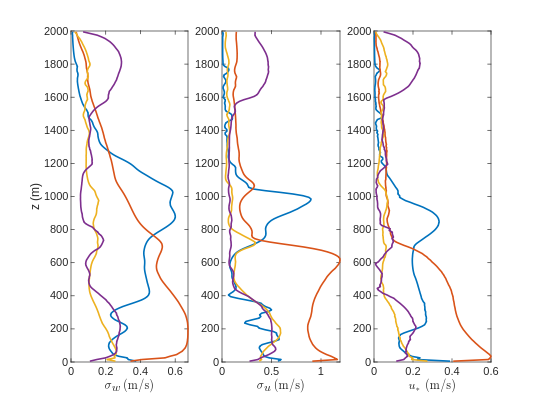

set(gcf,'color','w')

figure
tiledlayout(1,3,"TileSpacing","tight")
nexttile
plot(stdW1,z,'linewidth',1.2)
ylabel('z (m)')
xlabel('$\sigma_w$ (m/s)','interpreter','latex')
nexttile
plot(stdU1,z,'linewidth',1.2)
xlabel('$\sigma_u$ (m/s)','interpreter','latex')
nexttile
plot(u_star1,z,'linewidth',1.2)
xlabel('$u_*$ (m/s)','interpreter','latex')

set(gcf,'color','w')

### Train the ANN on 30 samples 

Nsamples = 48; % Total number of subsamples extracted from the dataset
Nz = numel(z);


% Each subsamples is averaged over 10 min intervals
tStart = NaT(1,Nsamples);
tEnd = NaT(1,Nsamples);
for ii=1:Nsamples
    tStart(ii) = datetime(2013,11,08,12,0,0) + hours(1*(ii-1));
    tEnd(ii) = tStart(ii)+minutes(10);
end
[U,V,H,stdU1,stdV1,stdW1,u_star1,wT1,theta1,L] = getSubSamples(t,tStart,tEnd,...
    u,v,stdU,stdV,stdW,u_star,wT,theta);

% Prepare the data set for training (30 of the 48 samples)
indSamples = [1:30]; 
[p,indMinZ] = min(abs(z-10));
[p,indMaxZ] = min(abs(z-1000));
indZ = [indMinZ:1:indMaxZ];

% Train the ANN
z1 = repmat(z,[numel(indSamples),1]);
[net] = get_stdU(z1(:,[indMinZ:indMaxZ]),...
    stdW1(indSamples,[indMinZ:indMaxZ]),...
    U(indSamples,[indMinZ:indMaxZ]),...
    V(indSamples,[indMinZ:indMaxZ]),...
    stdU1(indSamples,[indMinZ:indMaxZ]),'hiddenLayerSize',20);

### Test the ANN on sample no 40

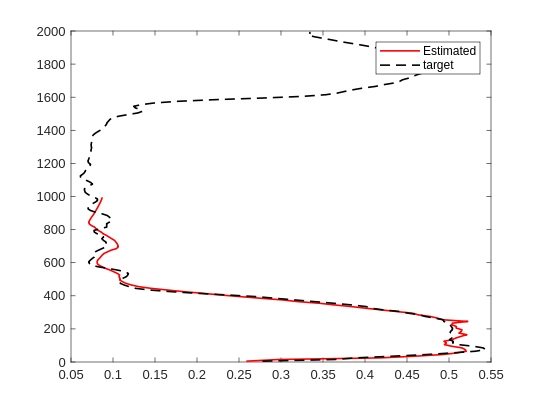

% The sample no 40 is chosen
indTarget =  [40];
% Inout preparation
clear x
x(1,:) = z([indMinZ:indMaxZ]);
x(2,:) = stdW1(indTarget,[indMinZ:indMaxZ]);
x(3,:) = U(indTarget,[indMinZ:indMaxZ]);
x(4,:) = V(indTarget,[indMinZ:indMaxZ]);
% use the trained ANN
y = net(x);

% Compare the estimated and real profiles
clf;close all;
figure
plot(y,z([indMinZ:indMaxZ]),'r','linewidth',1.2)
hold on
plot(stdU1(indTarget,:),z(1,:),'k--','linewidth',1.2)
% plot(stdU1(indTarget,indZ),z(1,indZ),'b+')
legend('Estimated','target')